## AAE364 HW10 

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE364\matlab\matlab_output\hw10';
set(groot, 'defaulttextinterpreter',"latex");
set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter',"latex");

% Bode plot options
opts_bd = bodeoptions('cstprefs');
opts_bd.Title.Interpreter = "latex";
opts_bd.XLabel.Interpreter = "Latex";
opts_bd.YLabel.Interpreter = "Latex";
opts_bd.Grid = 'on';
% Nyquist plot options
opts_nq = nyquistoptions("cstprefs");
opts_nq.Title.Interpreter = 'latex';
opts_nq.XLabel.Interpreter = "Latex";
opts_nq.YLabel.Interpreter = "Latex";
opts_nq.Grid = 'on';

### B-7-3

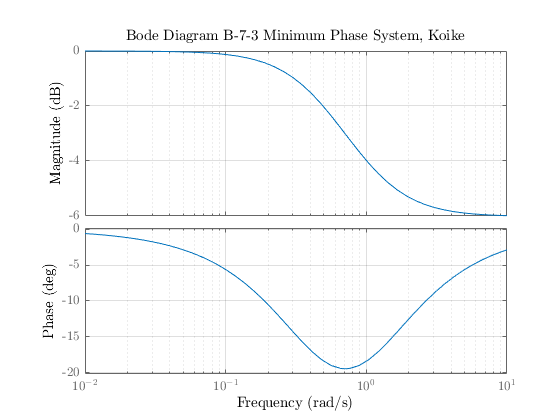

% Minimum Phase System
num = [1 1];
den = [2 1];
G = tf(num,den);
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram B-7-3 Minimum Phase System, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"B-7-3_min_bode.png"));

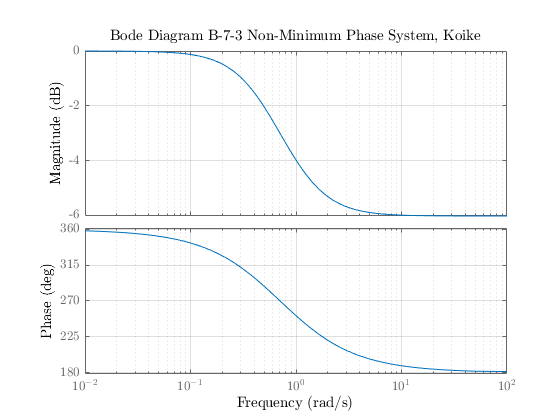


% Non-minimum Phase System
num = [-1 1];
den = [2 1];
G = tf(num,den);
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram B-7-3 Non-Minimum Phase System, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"B-7-3_nonmin_bode.png"));

### B-7-8

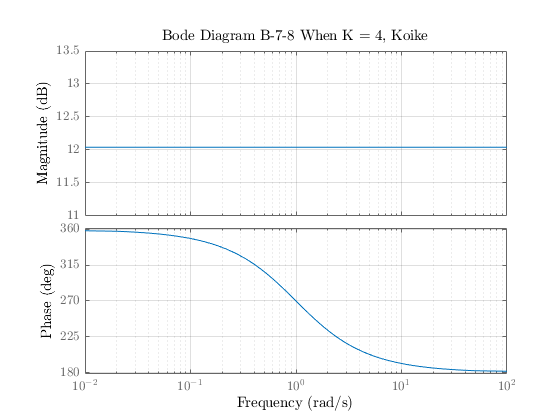

% |K| > 1
% Draw the Bode plot 
K = 4;
num = K*[-1 1];
den = [1 1];
G = tf(num,den);
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram B-7-8 When K = 4, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"B-7-8_bode_K=4.png"));

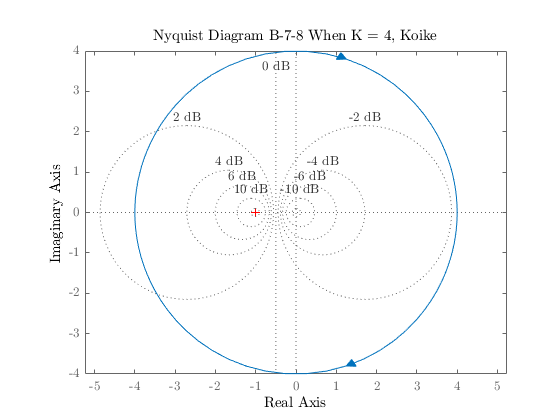


% Nyquist plot
fig = figure("Renderer","painters");
    opts_nq.Title.String = "Nyquist Diagram B-7-8 When K = 4, Koike";
    nyquistplot(G,opts_nq);
    axis equal;
saveas(fig,fullfile(fdir,"B-7-8_nyquist_K=4.png"));

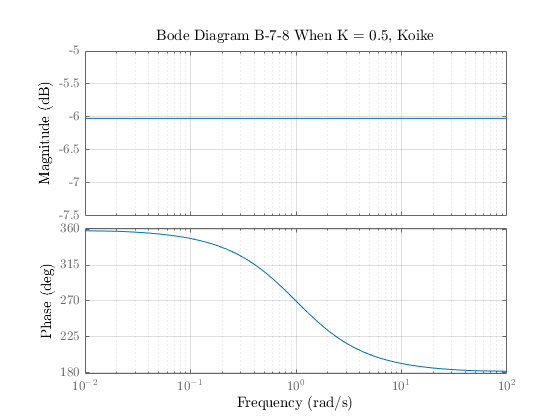


% |K| <= 1
% Draw the Bode plot 
K = 0.5;
num = K*[-1 1];
den = [1 1];
G = tf(num,den);
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram B-7-8 When K = 0.5, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"B-7-8_bode_K=0.5.png"));

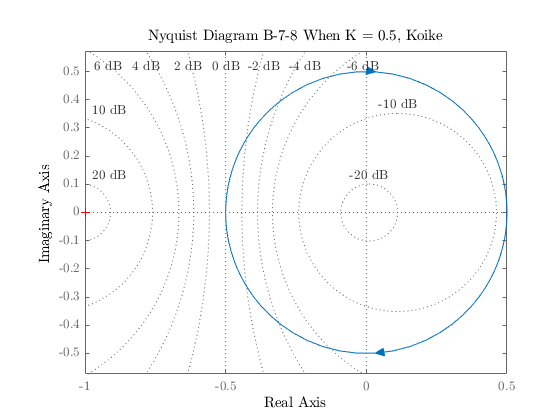


% Nyquist plot
fig = figure("Renderer","painters");
    opts_nq.Title.String = "Nyquist Diagram B-7-8 When K = 0.5, Koike";
    nyquistplot(G,opts_nq);
    axis equal;
saveas(fig,fullfile(fdir,"B-7-8_nyquist_K=0.5.png"));

### B-7-10

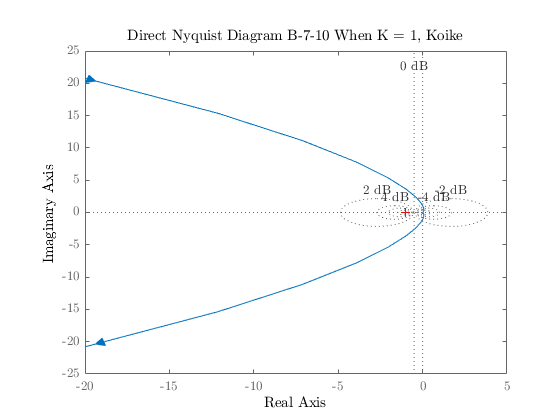

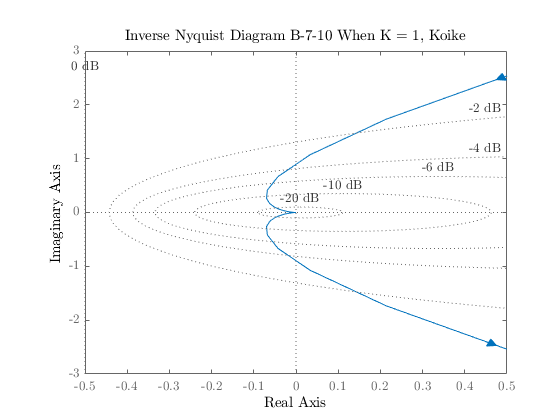

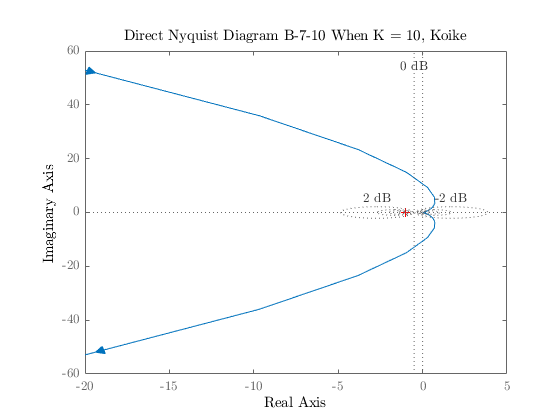

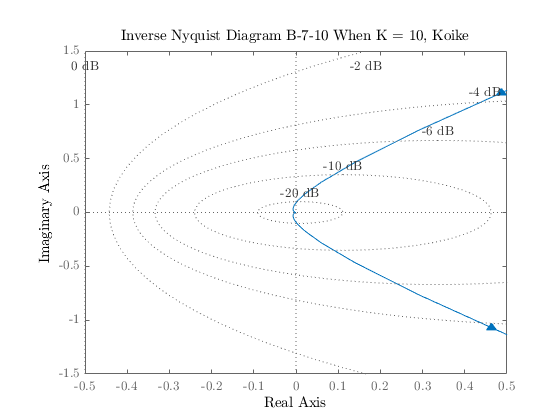

close all;
% Define the OL transfer function  
num = 5*[0.5 1];
den = conv([2 1],[10 1]);
den = conv(den,20*[1 0 0]);
w = logspace(-1,2,200);
for i = 0:1
    switch i
        case 0
            K = 1; G = tf(K*num,den);
            [mag,phase,w] = bode(G,w);
            mag1dB = 20*log10(mag(:)); phase1 = phase(:);
        case 1
            K = 10; G = tf(K*num,den);
            [mag,phase,w] = bode(G,w);
            mag2dB = 20*log10(mag(:)); phase2 = phase(:);
    end
        
    % Direct Nyquist plot
    fig1 = figure(1+i);
        title_txt = sprintf("Direct Nyquist Diagram B-7-10 When K = %d, Koike",K);
        opts_nq.Title.String = title_txt;
        nyquistplot(G,opts_nq);
        xlim([-20 5])
        file_txt = sprintf("B-7-10_dir_nyquist_K=%d.png",K);
    saveas(fig1,fullfile(fdir,file_txt));
    
    % Inverse Nyquist plot
    fig2 = figure(3+i);
        title_txt = sprintf("Inverse Nyquist Diagram B-7-10 When K = %d, Koike",K);
        opts_nq.Title.String = title_txt;
        nyquistplot(inv(G),opts_nq);
        xlim([-0.5 0.5])
        file_txt = sprintf("B-7-10_inv_nyquist_K=%d.png",K);
    saveas(fig2,fullfile(fdir,file_txt));
end

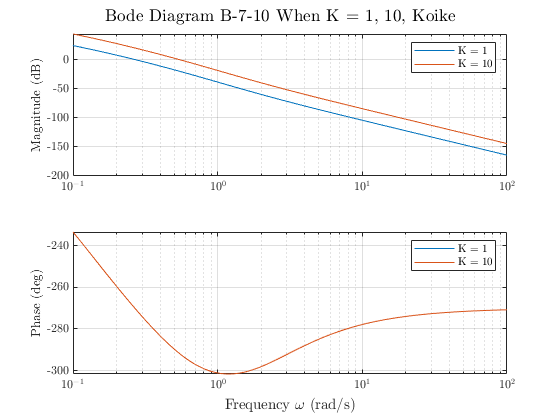


% Bode Plot
fig = figure("Renderer","painters");
    subplot(2,1,1);
        semilogx(w,mag1dB); ylabel('Magnitude (dB)');
        grid on; hold on;
        semilogx(w,mag2dB); hold off; legend('K = 1','K = 10');
    subplot(2,1,2);
        semilogx(w,phase1); ylabel('Phase (deg)');
        grid on; hold on; 
        semilogx(w,phase2); hold off; legend('K = 1','K = 10');
    % Give common xlabel, ylabel and title to your figure
    han = axes(fig,'visible','off'); 
    han.XLabel.Visible = 'on';
    xlabel(han,'Frequency $\omega$ (rad/s)');
    title_txt = sprintf("Bode Diagram B-7-10 When K = %d, %d, Koike",1,10);
    sgtitle(title_txt);
    file_txt = sprintf("B-7-10_bode_K=%d.png",K);
saveas(fig,fullfile(fdir,file_txt));

### B-7-13

% Define the transfer function 
num = [0 1];
den = [1 0.2 1 1];
p = roots(den); 
a = -p(3)

a = 0.7246

b = p(1) + p(2)

b = 0.5246

c = p(1)*p(2)

c = 1.3801

b_c = b/c

b_c = 0.3801

Q = 1/a/c

Q = 1

c_sqrt = sqrt(c)

c_sqrt = 1.1748

G = tf(num,den);

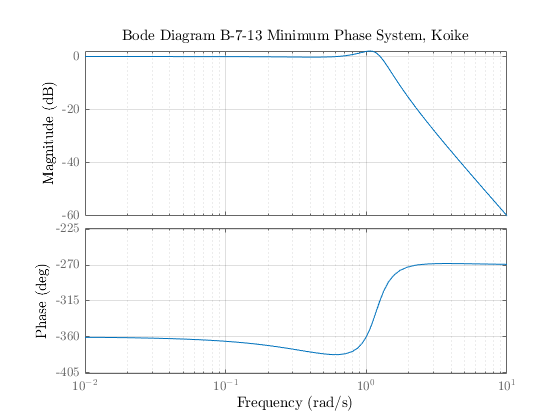

fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram B-7-13 Minimum Phase System, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"B-7-13_bode.png"));

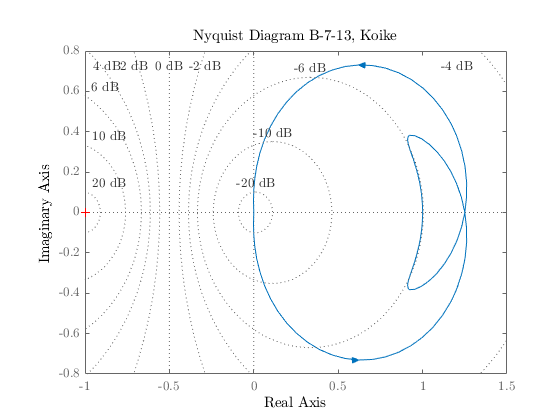

% Nyquist Plot
fig = figure("Renderer","painters");
    opts_nq.Title.String = "Nyquist Diagram B-7-13, Koike";
    nyquistplot(G,opts_nq);
saveas(fig,fullfile(fdir,"B-7-13_nyquist.png"));

### B-7-15

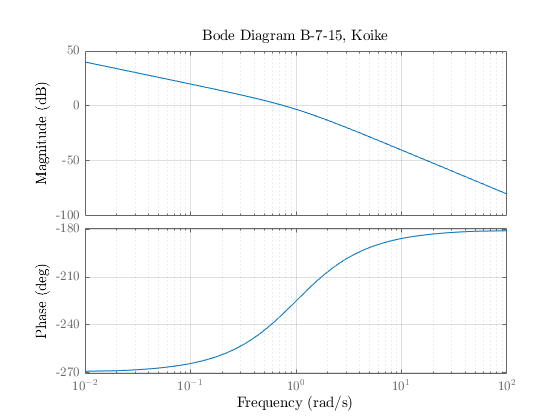

num = [0 1];
den = conv([1 0],[1 -1]);
G = tf(num,den);
% Bode plot
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram B-7-15, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"B-7-15_bode.png"));

% some calculations
arr_log = [30 20 -3 -46 -65];
arr = 10.^(arr_log/20);

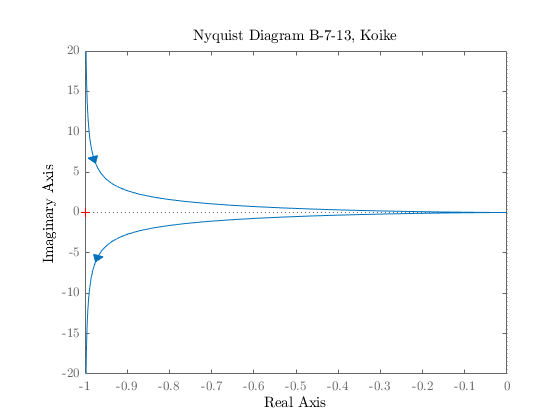

% Nyquist Plot
fig = figure("Renderer","painters");
    opts_nq.Title.String = "Nyquist Diagram B-7-13, Koike";
    opts_nq.Grid = 'off';
    nyquistplot(G,opts_nq);
saveas(fig,fullfile(fdir,"B-7-15_nyquist.png"));

### P2

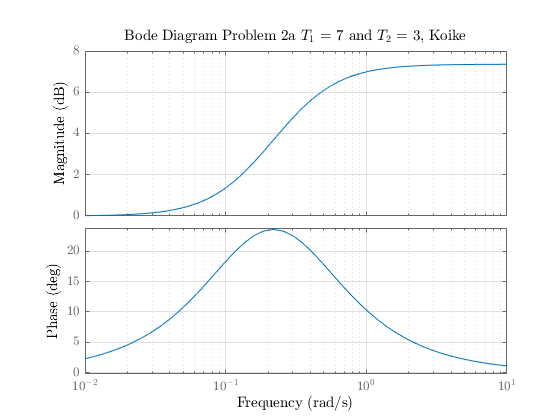

% (a)
num = [7 1];
den = [3 1];
G = tf(num,den);
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram Problem 2a $T_1$ = 7 and $T_2$ = 3, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"P2-a_bode.png"));

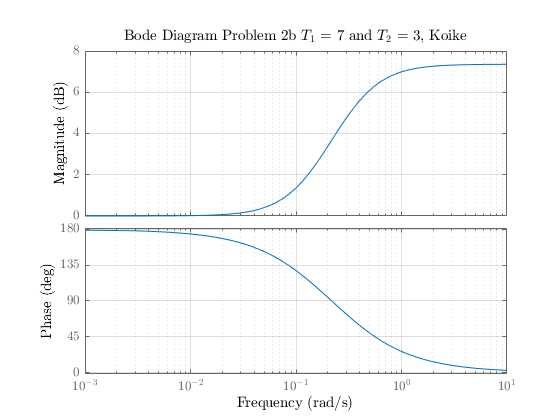


% (b)
num = [7 -1];
den = [3 1];
G = tf(num,den);
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram Problem 2b $T_1$ = 7 and $T_2$ = 3, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"P2-b_bode.png"));

% (c)
num = [-7 1];
den = [3 1];
G = tf(num,den)

G =
 
  -7 s + 1
  --------
  3 s + 1
 
Continuous-time transfer function.



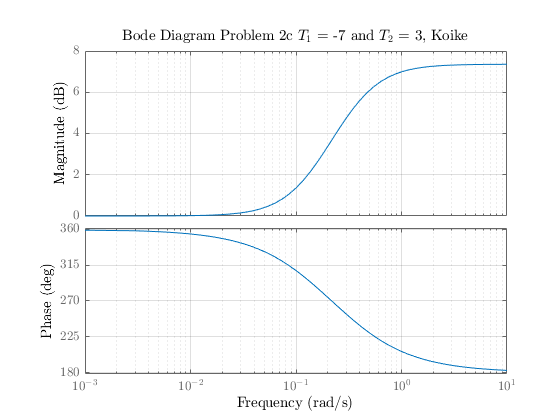

fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram Problem 2c $T_1$ = -7 and $T_2$ = 3, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"P2-c_bode.png"));